# **demo06 of Im2mesh package**

demo06 - Parameter hmax and grad_limit in mesh generation

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with [Im2mesh_GUI](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh) before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package. No need to install any MATLAB toolboxes when running this demo.

## Initialize

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called MESH2D (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Import image

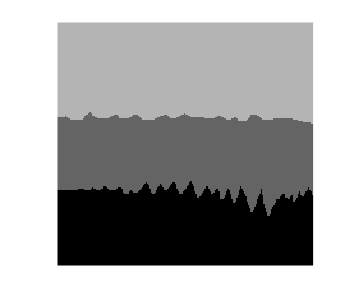

im = imread('Transition.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

## hmax = 8

opt = [];       % reset opt
opt.grad_limit = 0.25;
opt.hmax = 8;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                163                290
         10                202                870
         13                203                964


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                365                290
         13                377                290
         20                381               3861
         27                381               4499


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                176               4461



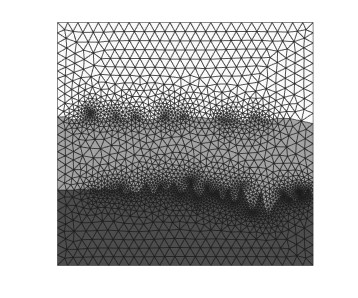


plotMeshes( vert, tria, tnum )

We can see that the max mesh size is limited by the parameter hmax.

## hmax = 500

Let's use a much larger hmax to see how things are changing.

opt = [];       % reset opt
opt.grad_limit = 0.25;
opt.hmax = 500;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                163                290
         10                202                870
         13                203                964


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          7                335                290
         10                337               1849
         20                339               4111
         21                339               4115


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                197               4081



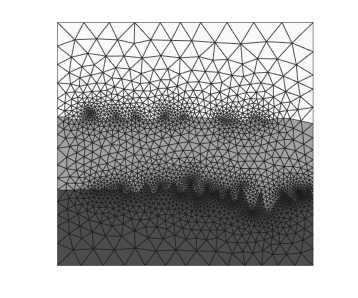

plotMeshes( vert, tria, tnum )

Now, the max mesh size is much larger. Note that hmax is a upper bound for the max mesh size. There exists boundary edge contraints and gradient-limt, so the max mesh size in the generated mesh can not reach hmax.

## grad_limit = 0.5

opt = [];       % reset opt
opt.grad_limit = 0.5;
opt.hmax = 500;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                163                290
         10                202                870
         13                203                964


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                283                290
         10                300               2162
         20                306               2518
         20                306               2518


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                 42               2470
     

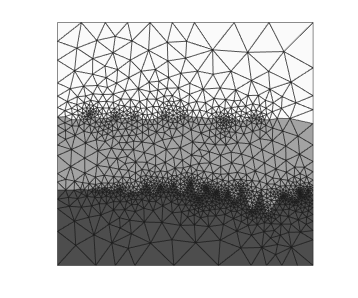

plotMeshes( vert, tria, tnum )

We can evaluate the mesh quality.

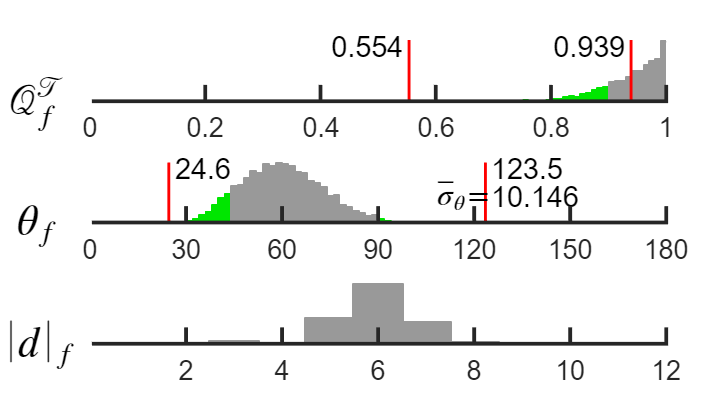

tricost( vert, tria );

## grad_limit = 0.25

Let's use a smaller grad_limit to see how things are changing.

opt = [];       % reset opt
opt.grad_limit = 0.25;
opt.hmax = 500;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                163                290
         10                202                870
         13                203                964


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          7                335                290
         10                337               1849
         20                339               4111
         21                339               4115


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                197               4081



plotMeshes( vert, tria, tnum )

We can evaluate the mesh quality again.

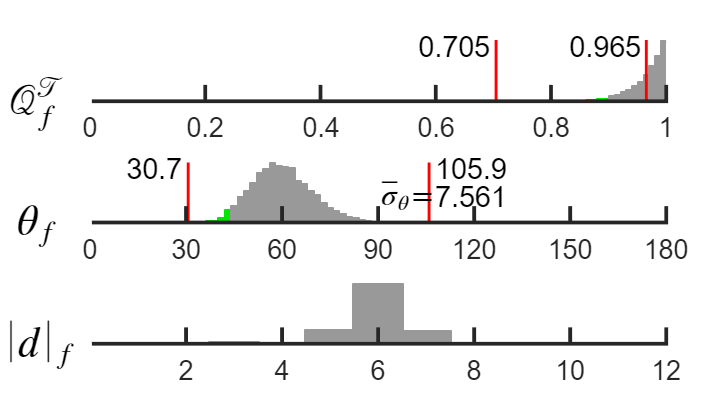

tricost( vert, tria );

Very good!

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo